Demo code for Figure Supp 5 of Idesis (2022) - Edge centric analysis of stroke patients. An alternative approach for biomarkers of lesion recovery

Edge-centric code adapted from Faskowitz, J. et al (2020) and Zamani Esfahalani (2020)

(https://github.com/brain-networks)

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

Create fake data of 5 stroke patients

amount_of_patients= 5; %Number for demo
for subj = 1:amount_of_patients
    ts_patients(:,:,subj)= ts.*(randn(1200,200)*4); %original ts plus a bigger factor random amount to make every subject different
end

High amplitude - Patients

for subj = 1:size(ts_patients,3)
    ts = ts_patients(:,:,subj);
    ts = zscore(ts); % z-score time series
    [ntime,nnodes] = size(ts); % get dimensions
    nedges = nnodes*(nnodes - 1)/2; % calculate number of edges
    [u,v] = find(triu(ones(nnodes),1)); % indices of unique edges (upper triangle)
    idx = (v - 1)*nnodes + u;
    fc = corr(ts); %% calculate static fc
    ets = ts(:,u).*ts(:,v); %% generate edge time series
    fc_upper_triangle = fc(idx);
    rms = sum(ets.^2,2).^0.5; % calculate co-fluctuation amplitude at each frame
    frackeep = 0.1; % fraction of high- and low-amplitude frames to retain
    nkeep = round(ntime*frackeep);
    [~,idxsort] = sort(rms,'descend'); % sort co-fluctuation amplitude
    
    boundaries = [0:length(ts)/10:length(ts)];
    % estimate fc using just high-amplitude frames
    fctop_10 = corr(ts(idxsort(boundaries(1)+1:boundaries(2)),:)); fctop_10(isnan(fctop_10)) = 0;
    fctop_20 = corr(ts(idxsort(boundaries(2)+1:boundaries(3)),:)); fctop_20(isnan(fctop_20)) = 0;
    fctop_30 = corr(ts(idxsort(boundaries(3)+1:boundaries(4)),:)); fctop_30(isnan(fctop_30)) = 0;
    fctop_40 = corr(ts(idxsort(boundaries(4)+1:boundaries(5)),:)); fctop_40(isnan(fctop_40)) = 0;
    fctop_50 = corr(ts(idxsort(boundaries(5)+1:boundaries(6)),:)); fctop_50(isnan(fctop_50)) = 0;
    fctop_60 = corr(ts(idxsort(boundaries(6)+1:boundaries(7)),:)); fctop_60(isnan(fctop_60)) = 0;
    fctop_70 = corr(ts(idxsort(boundaries(7)+1:boundaries(8)),:)); fctop_70(isnan(fctop_70)) = 0;
    fctop_80 = corr(ts(idxsort(boundaries(8)+1:boundaries(9)),:)); fctop_80(isnan(fctop_80)) = 0;
    fctop_90 = corr(ts(idxsort(boundaries(9)+1:boundaries(10)),:)); fctop_90(isnan(fctop_90)) = 0;
    fctop_100 = corr(ts(idxsort(boundaries(10)+1:boundaries(11)-4),:)); fctop_100(isnan(fctop_100)) = 0;

    
    corr_top_10(subj)=corr(fctop_10(idx),fc(idx));
    corr_top_20(subj)=corr(fctop_20(idx),fc(idx));
    corr_top_30(subj)=corr(fctop_30(idx),fc(idx));
    corr_top_40(subj)=corr(fctop_40(idx),fc(idx));
    corr_top_50(subj)=corr(fctop_50(idx),fc(idx));
    corr_top_60(subj)=corr(fctop_60(idx),fc(idx));
    corr_top_70(subj)=corr(fctop_70(idx),fc(idx));
    corr_top_80(subj)=corr(fctop_80(idx),fc(idx));
    corr_top_90(subj)=corr(fctop_90(idx),fc(idx));
    corr_top_100(subj)=corr(fctop_100(idx),fc(idx));
end


Create fake data for lesion volume

lesion_volume=rand(1,length(corr_top_10));


Regression of each decile

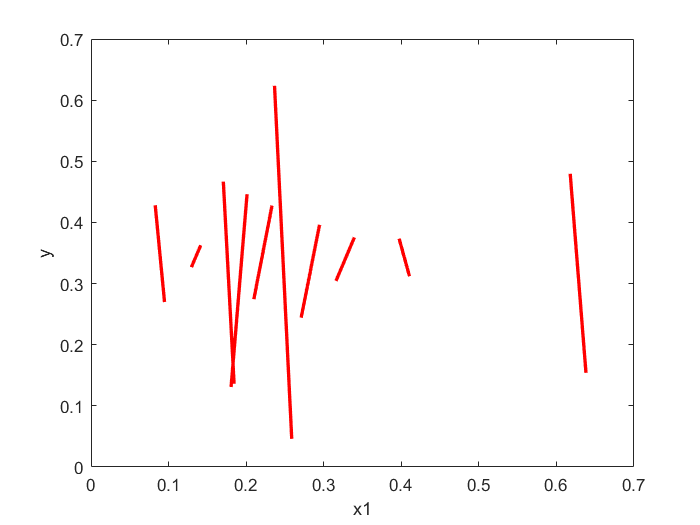

list_of_predictors = {corr_top_10...
                      corr_top_20...
                      corr_top_30...
                      corr_top_40...
                      corr_top_50...
                      corr_top_60...
                      corr_top_70...
                      corr_top_80...
                      corr_top_90...
                      corr_top_100};
figure();clf();
for  m=1:length(list_of_predictors)
    x=list_of_predictors{m};
    mdlr = fitlm(x,lesion_volume);
    regr_plot=plot(mdlr);
    delete(regr_plot(1));
    regr_plot(end-1,1).Visible='off';
    regr_plot(end,1).Visible='off';
    set([regr_plot(2)],'color',[1, 0, 0, 1-(m/10)],'LineWidth',2);
    hold on;
    clear regr_plot
end
legend('off');
title('');